clc;
clear all;

number_of_runs = 5000;

L = 10;                   
EI = 4.2e7

EI = 42000000

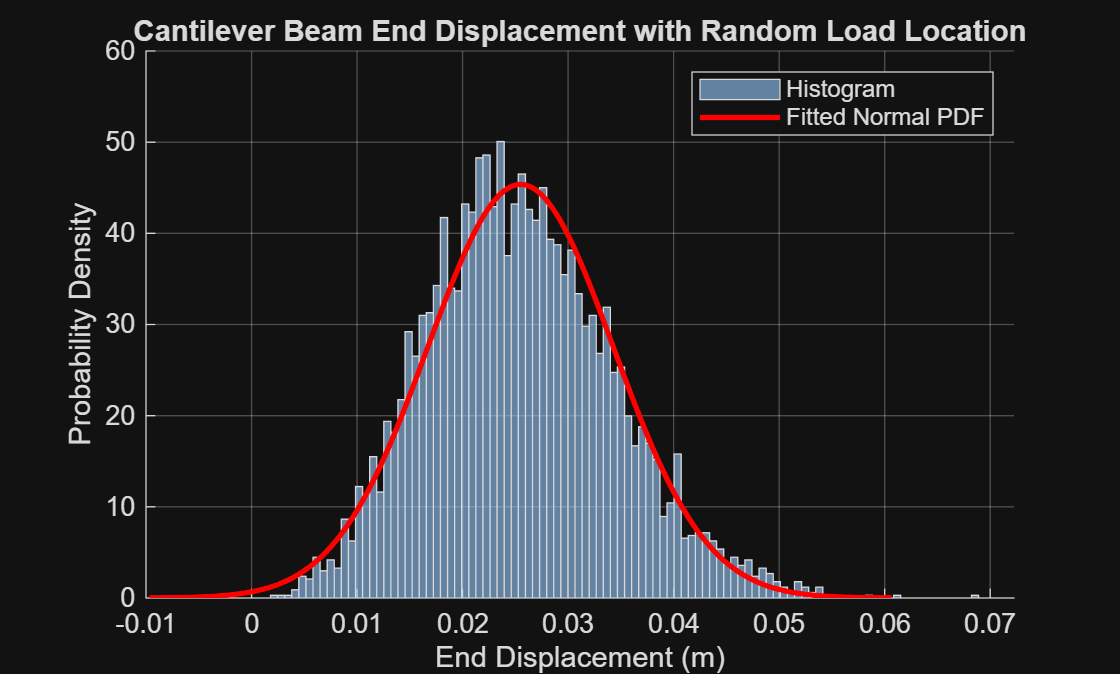

P = 10000;                

mu_x = L / 2;
sigma_x = 0.3 * L;
x_samples = mvnrnd(mu_x, sigma_x, number_of_runs, 1);
x_samples = min(max(x_samples, 0), L); 

N = 5;                    
Nodes = N + 1;
partLength = L / N;

% DOF mapping
dof = zeros(N, 4);
for i = 1:N
    dof(i,:) = [2*i - 1, 2*i, 2*i + 1, 2*i + 2];
end

end_displacement = zeros(number_of_runs, 1);
mean_vals = zeros(number_of_runs,1);
std_vals = zeros(number_of_runs,1);

for n = 1:number_of_runs
    x_load = x_samples(n);  % Load location

    % Identify element containing the load
    element_index = min(floor(x_load / partLength) + 1, N);
    local_x = x_load - (element_index - 1) * partLength;
    xi = local_x / partLength;

    % Global stiffness matrix
    Keq = zeros(Nodes * 2);
    for i = 1:N
        Le = partLength;
        k = (EI / Le^3) * ...
            [12, 6*Le, -12, 6*Le;
             6*Le, 4*Le^2, -6*Le, 2*Le^2;
            -12, -6*Le, 12, -6*Le;
             6*Le, 2*Le^2, -6*Le, 4*Le^2];

        for j = 1:4
            for p = 1:4
                Keq(dof(i,j), dof(i,p)) = Keq(dof(i,j), dof(i,p)) + k(j,p);
            end
        end
    end

    N1 = 1 - 3*xi^2 + 2*xi^3;
    N2 = local_x - 2*local_x^2/partLength + local_x^3/partLength^2;
    N3 = 3*xi^2 - 2*xi^3;
    N4 = -local_x^2/partLength + local_x^3/partLength^2;
    f_local = P * [N1; N2; N3; N4];

    F = zeros(Nodes * 2, 1);
    F(dof(element_index, :)) = F(dof(element_index, :)) + f_local;

    fixed_dofs = [1, 2];
    free_dofs = setdiff(1:Nodes*2, fixed_dofs);

    K_reduced = Keq(free_dofs, free_dofs);
    F_reduced = F(free_dofs);
    d = zeros(Nodes * 2, 1);
    d(free_dofs) = K_reduced \ F_reduced;

    % Store end displacement (Node 6 = DOF 11)
    end_displacement(n) = d(11);

    mean_vals(n) = mean(end_displacement(1:n));
    std_vals(n) = std(end_displacement(1:n));

end

% Statistics
mu_d = mean(end_displacement);
sigma_d = std(end_displacement);
x = linspace(mu_d - 4*sigma_d, mu_d + 4*sigma_d, 1000);
pdf_values = normpdf(x, mu_d, sigma_d);

% Plotting
figure;
hold on;
histogram(end_displacement, 100, 'Normalization', 'pdf', 'FaceColor', [0.6 0.8 1]);
plot(x, pdf_values, 'r-', 'LineWidth', 2);
xlabel('End Displacement (m)');
ylabel('Probability Density');
title('Cantilever Beam End Displacement with Random Load Location');
legend('Histogram', 'Fitted Normal PDF');
grid on;

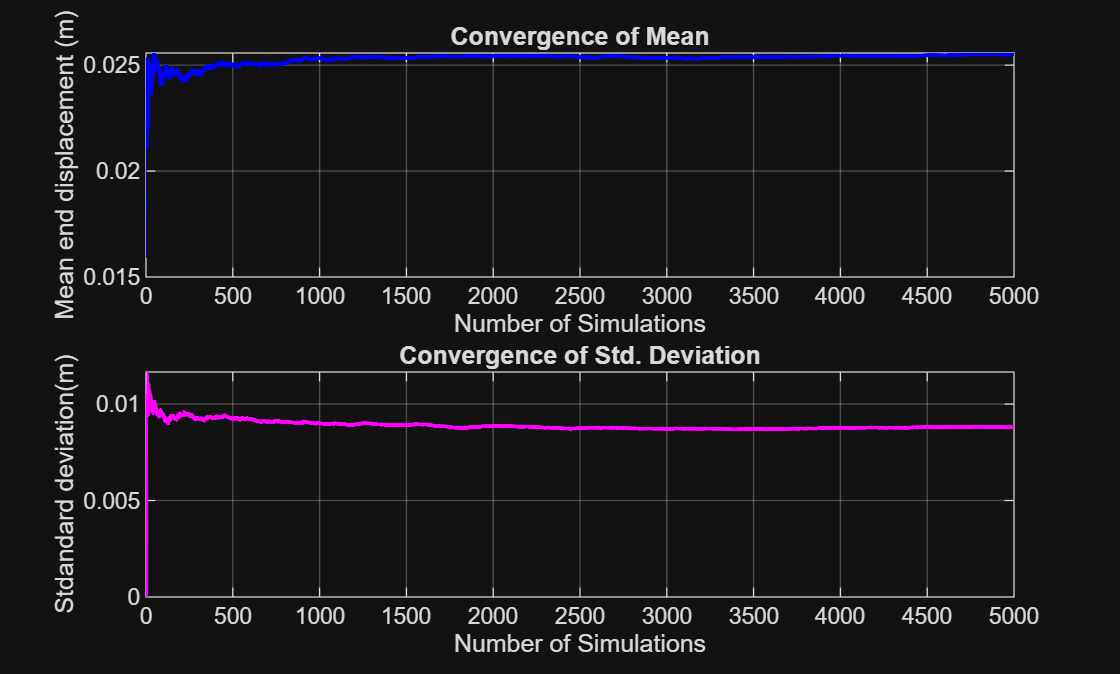



%plotting convergence of mean and std deviation
figure;
subplot(2, 1, 1);
plot(1:number_of_runs, mean_vals, 'b', 'LineWidth',1.5);
xlabel('Number of Simulations');
ylabel('Mean end displacement (m)');
title('Convergence of Mean');
grid on;

subplot(2,1,2);
plot(1:number_of_runs, std_vals, 'm', 'LineWidth',1.5);
xlabel('Number of Simulations');
ylabel('Stdandard deviation(m)');
title('Convergence of Std. Deviation');
grid on;


fprintf('Final Mean of End Displacement: %.6f m\n', mu_d);

Final Mean of End Displacement: 0.025496 m


fprintf('Final Std Dev of End Displacement: %.6f m\n', sigma_d);

Final Std Dev of End Displacement: 0.008794 m
